# Clean Messy and Missing Data in Tables

This example shows how to clean and reorganize a table that has messy and missing data values. First, you can identify missing data by using the Import Tool or by using functions such as the `summary` and `ismissing` functions. Next, you can standardize, fill, or remove missing values by using the `standardizeMissing`, `fillmissing`, or `rmmissing` functions or the [Clean Missing Data](docid:matlab_ref#mw_097f17ef-5458-45c8-a3c3-8faae3720399) task in the Live Editor. Then, you can reorganize your table by rearranging table rows and variables by using the `sortrows` and `movevars` functions.

## Examine Data in File

Examine the data in the sample comma-separated value (CSV) file, `messy.csv`, by using the Import Tool. The tool previews the data and enables you to specify how to import the data. To examine `messy.csv` in the Import Tool, after opening this example in MATLAB®, on the **Home** tab, in the **Variable** section, click **Import Data**. Then, open `messy.csv` using the file selection dialog box. 

The Import Tool shows that `messy.csv` has five columns with text and numeric values.

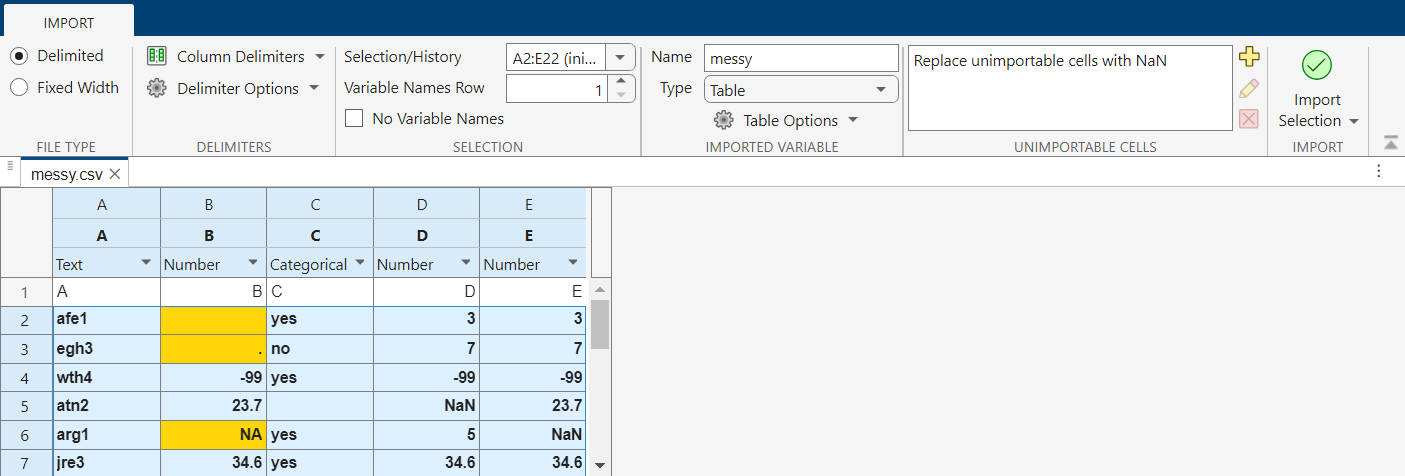

The file contains many different missing data indicators:

- Empty text

- Period (.)

- `NA`

- `NaN`

- `-99`

The Import Tool automatically recognizes (but does not visually highlight) some missing data indicators, such as `NaN` in numeric columns and empty text in text columns.

The tool highlights other indicators, such as the empty text, period, and `NA`, that occur in column `B`. These values are not standard missing values. However, nonnumeric values in a numeric column are likely to represent missing values. On the **Import** tab, in the **Unimportable Cells** section, you can add rules to treat these values as missing values.

When numeric data otherwise consists of positive values, a single negative value, such as `-99`, can be a flag for missing data. If a number such as `-99` represents missing data in your table, then you must specify that it is a missing value when you clean your table.

## Import Data as Table

You can use the `readtable` function to read the data from a file and import it as a table.

Import the data in `messy.csv` using the `readtable` function. To read text data into table variables that are string arrays, use the `TextType` name-value argument. To treat specified nonnumeric values in numeric columns as missing values, use the `TreatAsMissing` name-value argument. For columns `A` and `C` with text data, `readtable` imports any empty text as missing strings, which display as `<missing>`. For columns `B`, `D`, and `E` with numeric data, `readtable` imports empty text as `NaN` values, and also imports `.` and `NA` as `NaN` values when you specify them using `TreatAsMissing`. However, the values that are `-99` remain unchanged because they are numeric.

messyTable = readtable("messy.csv","TextType","string","TreatAsMissing",[".","NA"])

## View Summary of Table

To view a summary of the table, use the `summary` function. The summary shows the data type and other descriptive statistics for each table variable. For example, `summary` shows the number of missing values in each numeric variable of `messyTable`.

summary(messyTable)

## Find Rows with Missing Values

To find the rows of `messyTable` that have at least one missing value, use the `ismissing` function. If you have nonstandard missing values in your data, such as `-99`, you can specify it along with the standard missing values.

The output of `ismissing` is a logical array that identifies the elements of `messyTable` that have missing values.

missingElements = ismissing(messyTable,{string(missing),NaN,-99})

To create a logical vector that identifies rows that have missing values, use the `any` function.

rowsWithMissingValues = any(missingElements,2)

To index into the table and return only the rows that have missing values, use the logical vector `rowsWithMissingValues`.

missingValuesTable = messyTable(rowsWithMissingValues,:)

## Fill Missing Values

One strategy for cleaning the missing values in a table is to replace them with more meaningful values. You can replace nonstandard missing values by inserting standard missing values. Then you can fill missing values with adjusted values. For example, you can fill missing values with their nearest neighbors or with the mean value of a table variable.

In this example, `-99` is a nonstandard value for indicating a missing value. To replace the instances of `-99` with standard missing values, use the `standardizeMissing` function. `NaN` is the standard missing value for single-  and double-precision floating-point numeric arrays.

messyTable = standardizeMissing(messyTable,-99)

To fill missing values, use the `fillmissing` function. The function provides many methods that fill missing values. For example, fill missing values with their nearest neighbors that are not missing values.

filledTable = fillmissing(messyTable,"nearest")

## Remove Rows with Missing Values

Another strategy for cleaning the missing values in a table is to remove the rows that have them.

To remove rows that have missing values, use the `rmmissing` function.

remainingTable = rmmissing(messyTable)

## Sort and Rearrange Table Rows and Variables

Once you have cleaned the missing values in a table, you can organize it in other ways. For example, you can sort the rows of a table by the values in one or more variables.

Sort the rows by the values in the first variable, `A`.

sortedTable = sortrows(remainingTable)

Sort the rows in descending order by `C`, and then sort in ascending order by `A`.

sortedBy2Vars = sortrows(remainingTable,["C","A"],["descend","ascend"])

Sorting by `C`, the rows are grouped first by `"yes"`, followed by `"no"`. Then sorting by `A`, the rows are listed alphabetically.

To reorder the table so that `A` and `C` are next to each other, use the `movevars` function.

sortedRowsAndMovedVars = movevars(sortedBy2Vars,"C","After","A")

You can also reorder table variables by indexing. Use smooth parentheses and a variable index that specifies the order of the variables in the output table.

sortedRowsAndMovedVars = sortedBy2Vars(:,["A","C","B","D","E"])

*Copyright 2024 The MathWorks, Inc.*